clear all;
run("load_params_ResonantCase.m");

# 2.2 Position PID-controller

## 2.2.1

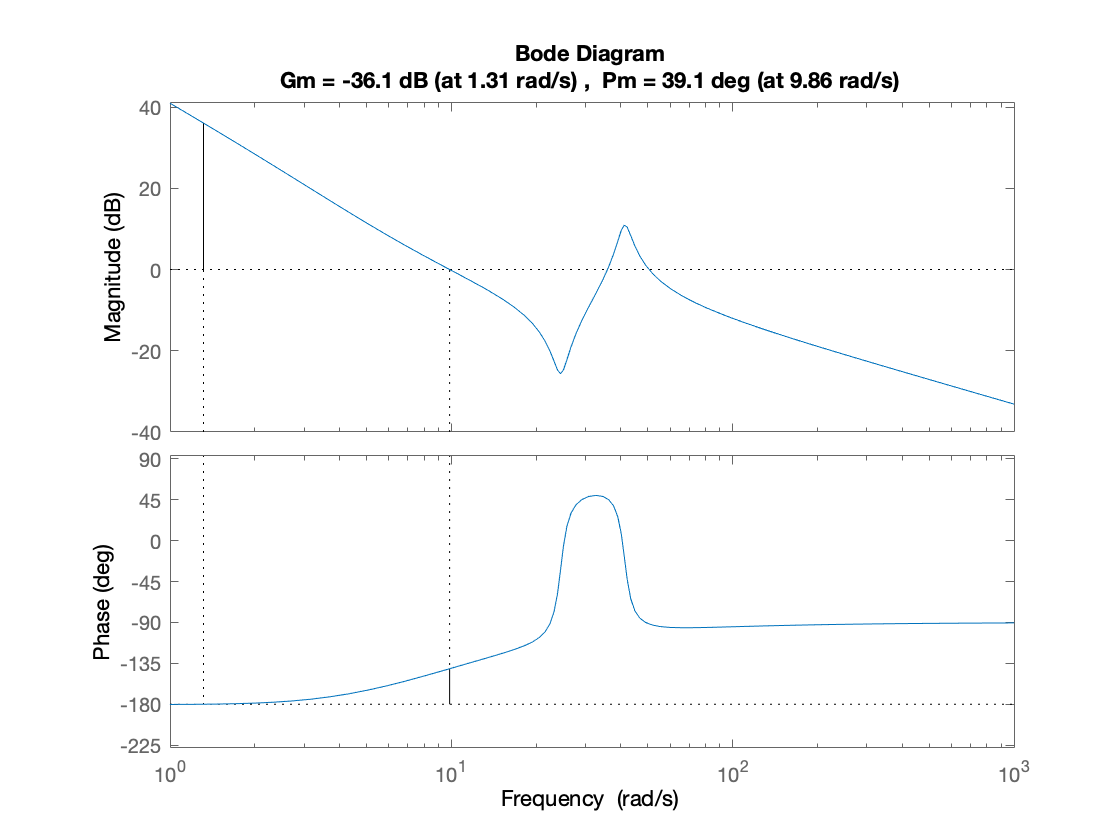

% Position controller specs
pctrl.ts = 0.85; % Desired settling time (at 5%)
pctrl.Mp = 0.3; % Desired overshoot

% Get specs for loop tf 
pctrl.d = log(1/pctrl.Mp) / sqrt(pi^2 + log(1/pctrl.Mp)^2); % Damping factor
pctrl.wgc = 3/pctrl.d/pctrl.ts; % Gain crossover freq [rad/s]          
pctrl.phim = 180/pi * atan(2*pctrl.d/sqrt(sqrt(1+4*pctrl.d^4)-2*pctrl.d^2)); % Phase margin [deg]

% Bode Method
[PID.kp, PID.ki, PID.kd] = BodMet(pctrl.wgc,pctrl.phim,simp_model.P_u_thh);

% Controller
s = tf('s');
PID.C = PID.kp + PID.ki/s + PID.kd*s; % Controller

% Verify frequency specs
figure;
margin(PID.C*simp_model.P_u_thh);

% Real derivator
PID.Tl = 1/(10*pctrl.wgc);

% Anti-Windup
AW.Kw = 5/pctrl.ts;

## 2.2.2 

% Open Simulink model
open_system('Simulink/PID.slx');

#### Simulations results [50°]

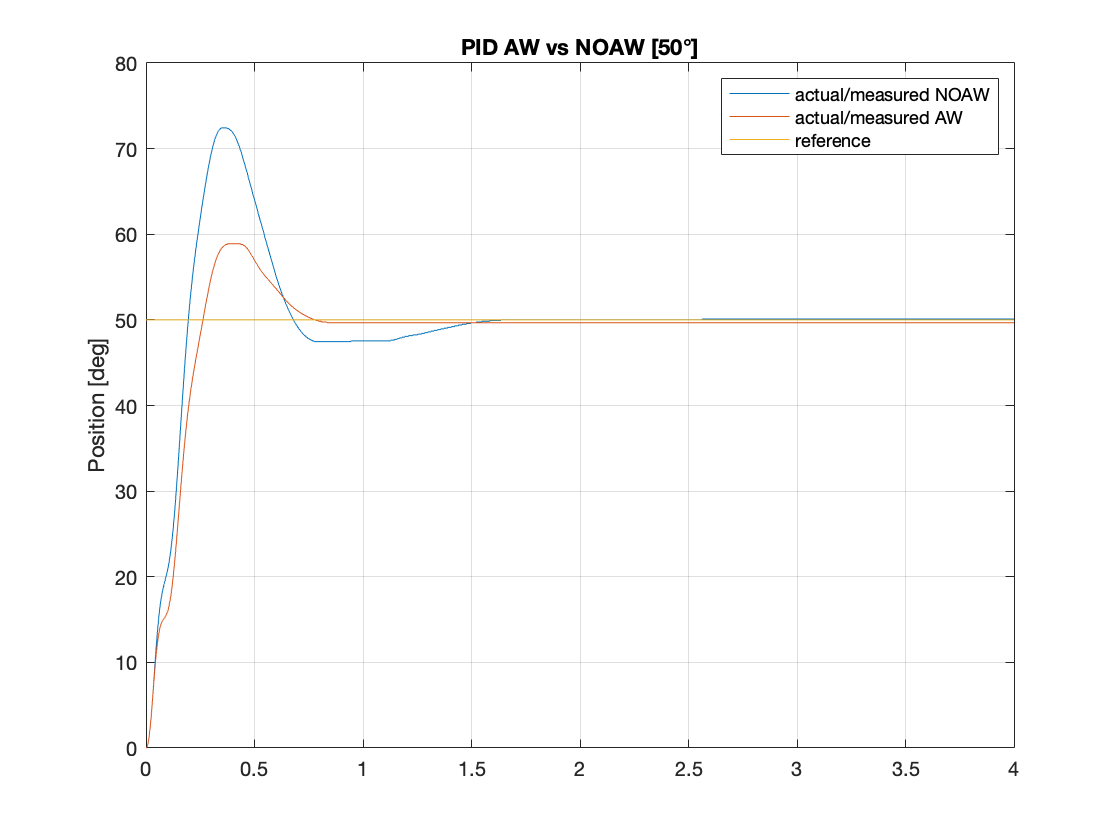

% Set parameters
set_param('PID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '4');
% Step
set_param('PID/Step','Time','0','Before','0','After','50');
set_param('PID/Step1','Time','0','Before','0','After','50');

% AW
set_param('PID/Enable_AW','Value','0'); % Disable AW
set_param('PID/Enable_AW1','Value','1'); % Enable AW

% Run simulation
sim('PID');

% Extract simulation results
PID.t = simres.time; % time vector 
PID.thh_NOAW = simres.signals(1).values(:,1); % hub position NOAW
PID.thh_AW = simres.signals(1).values(:,2); % hub position AW
PID.thh_Ref = simres.signals(1).values(:,3); % hub position reference


% Plot simulation results
figure
plot(PID.t, PID.thh_NOAW);
hold on;
plot(PID.t, PID.thh_AW);
hold on;
plot(PID.t, PID.thh_Ref);
ylabel('Position [deg]');
grid on;
title('PID AW vs NOAW [50°]');
legend('actual/measured NOAW', 'actual/measured AW', 'reference');

#### Simulations results [120°]

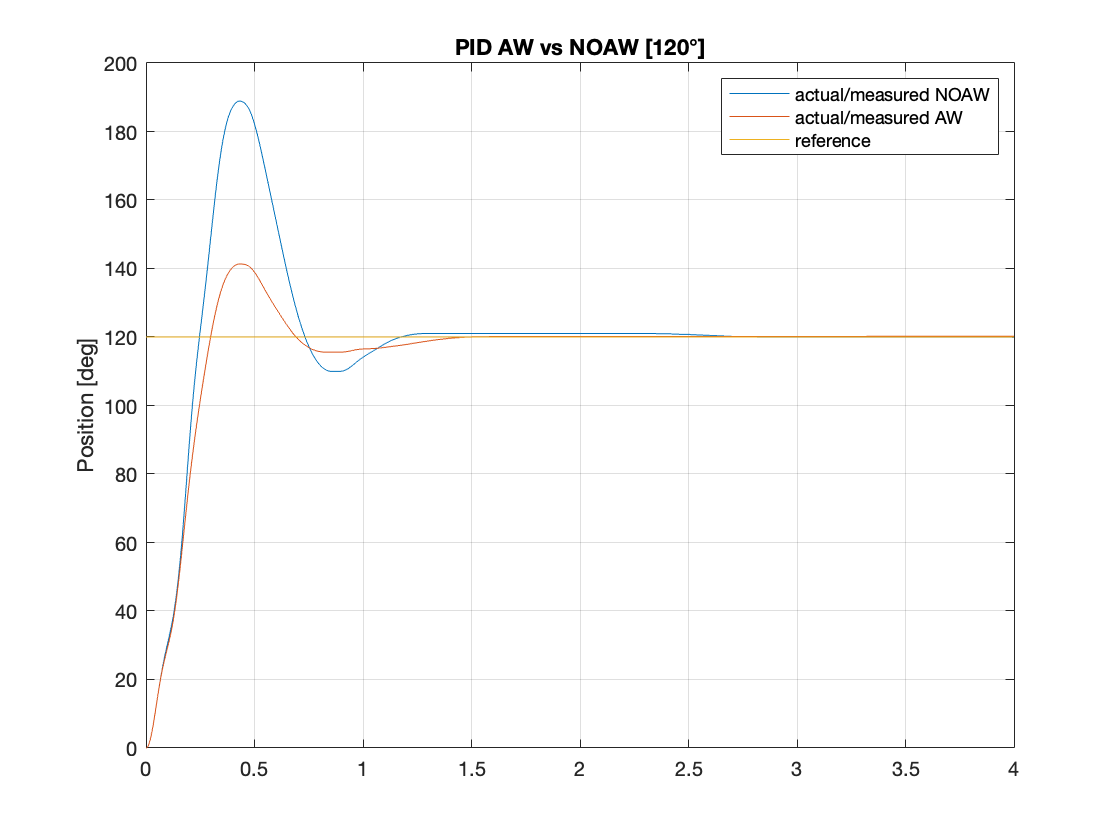

% Set parameters
set_param('PID', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '4');
% Step
set_param('PID/Step','Time','0','Before','0','After','120');
set_param('PID/Step1','Time','0','Before','0','After','120');

% Run simulation
sim('PID');

% Extract simulation results
PID.t = simres.time; % time vector 
PID.thh_NOAW = simres.signals(1).values(:,1); % hub position NOAW
PID.thh_AW = simres.signals(1).values(:,2); % hub position AW
PID.thh_Ref = simres.signals(1).values(:,3); % hub position reference


% Plot simulation results
figure
plot(PID.t, PID.thh_NOAW);
hold on;
plot(PID.t, PID.thh_AW);
hold on;
plot(PID.t, PID.thh_Ref);
ylabel('Position [deg]');
grid on;
title('PID AW vs NOAW [120°]');
legend('actual/measured NOAW', 'actual/measured AW', 'reference');

# 2.3 Position state–space control using eigenvalues placement design methods

% State-space model [th_h th_d w_h w_d]
state_space.A = [0 0 1 0;0 0 0 1;0 simp_model.k/(gbox.N^2*simp_model.Jeq) -(simp_model.Beq + mot.Kt*mot.Ke/simp_model.Req)/simp_model.Jeq 0;0 -simp_model.k/simp_model.Jb-simp_model.k/(simp_model.Jeq*gbox.N^2) -simp_model.Bb/simp_model.Jb+(simp_model.Beq+mot.Kt*mot.Ke/simp_model.Req)/(simp_model.Jeq) -simp_model.Bb/simp_model.Jb];
state_space.B = [0;0;mot.Kt*drv.dcgain/(gbox.N*simp_model.Jeq*simp_model.Req);-mot.Kt*drv.dcgain/(gbox.N*simp_model.Jeq*simp_model.Req)];
state_space.Bd = [0;0;-1/(gbox.N^2*simp_model.Jeq);1/(gbox.N^2*simp_model.Jeq)];
state_space.C = [1 0 0 0];

% Real derivative
der.wc = 2*pi*50;
der.d = 1/sqrt(2);
der.NUM = [der.wc^2 0];
der.DEN = [1 2*der.d*der.wc der.wc^2];


## 2.3.1 Nominal action

% Eigenvalues placement
eig.delta = log(1/pctrl.Mp)/(sqrt(pi^2 + log(1/pctrl.Mp)^2));
eig.wn = 3/(eig.delta*pctrl.ts);
eig.phi = atan2(sqrt(1-eig.delta^2),eig.delta);
nominal.lambda1 = eig.wn*exp(1i*(-pi+eig.phi));
nominal.lambda2 = eig.wn*exp(1i*(-pi-eig.phi));
nominal.lambda3 = eig.wn*exp(1i*(-pi+eig.phi/2));
nominal.lambda4 = eig.wn*exp(1i*(-pi-eig.phi/2));
nominal.lambdas = [nominal.lambda1 nominal.lambda2 nominal.lambda3 nominal.lambda4];

% Controller K
nominal.K = acker(state_space.A, state_space.B, nominal.lambdas);


% Nx, Nu
nominal.X = linsolve([state_space.A,state_space.B;state_space.C 0],[0;0;0;0;1]);
nominal.N_x = nominal.X(1:4,:);
nominal.N_u = nominal.X(5,:);

## 2.3.2

% Open Simulink model
open_system('Simulink/SS_eig_LQR.slx');

#### Simulations results [50°] 

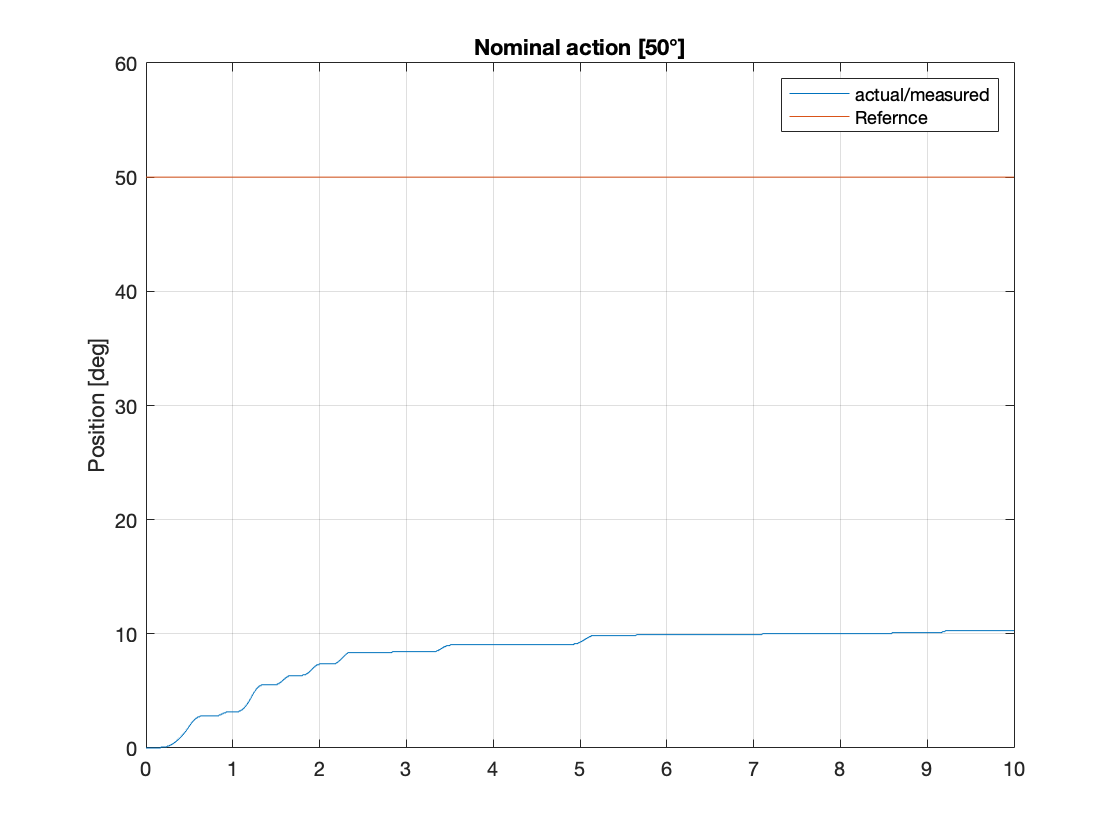

% Set parameters
set_param('SS_eig_LQR', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '10');
% Step
set_param('SS_eig_LQR/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('SS_eig_LQR/Enable Integral','Value','0'); % Nominal action ON
set_param('SS_eig_LQR/State-space Controller/Input feedforward gain','gain','nominal.N_u'); % Input feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedforward gain','gain','nominal.N_x'); % State feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','nominal.K'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','0'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
nominal.t = simres.time; % Time vector 
nominal.thh = simres.signals(1).values(:,1); % Hub position
nominal.Ref = simres.signals(1).values(:,2); % Reference


% Plot simulation results
figure
plot(nominal.t, nominal.thh);
hold on;
plot(nominal.t, nominal.Ref);
ylabel('Position [deg]');
ylim([0,60]);
grid on;
title('Nominal action [50°]');
legend('actual/measured', 'Refernce');

## 2.3.3 Integral action [OPTIONAL]

% Ae, Be, Ce 
robust.Ae = [0 state_space.C;[0;0;0;0] state_space.A];
robust.Be = [0;state_space.B];
robust.Ce = [0 state_space.C];

% Eigenvalues
robust.lambda1 = nominal.lambda1;
robust.lambda2 = nominal.lambda2;
robust.lambda3 = nominal.lambda3;
robust.lambda4 = nominal.lambda4;
robust.lambda5 = -eig.wn;
robust.lambdas = [robust.lambda1 robust.lambda2 robust.lambda3 robust.lambda4 robust.lambda5];

% Ke = [Ki, K]
robust.Ke = acker(robust.Ae, robust.Be, robust.lambdas);

robust.Ki = robust.Ke(:,1);
robust.K = robust.Ke(1,2:5);

## 2.3.4

#### Simulations results [50°] 

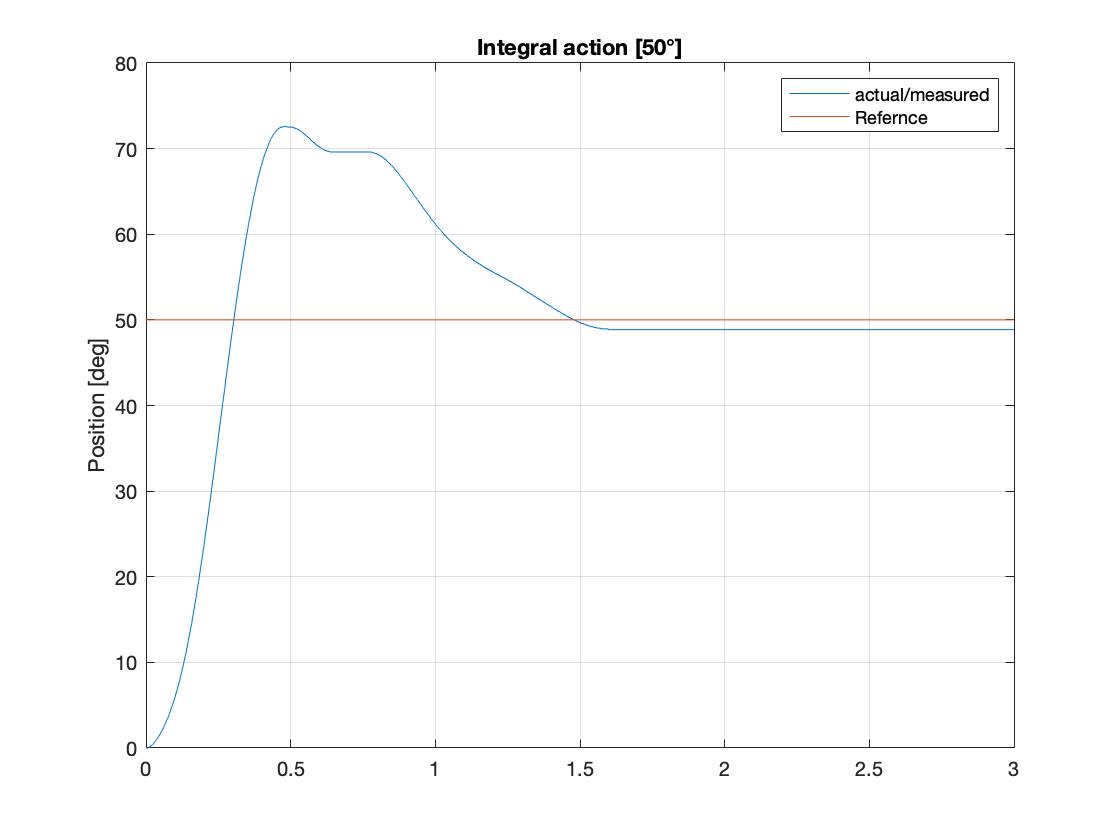

% Set parameters
set_param('SS_eig_LQR', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');

% State-space Controller
set_param('SS_eig_LQR/Enable Integral','Value','1'); % Integral action ON
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','robust.K'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','robust.Ki'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
robust.t = simres.time; % Time vector 
robust.thh = simres.signals(1).values(:,1); % Hub position
robust.Ref = simres.signals(1).values(:,2); % Reference


% Plot simulation results
figure
plot(robust.t, robust.thh);
hold on;
plot(robust.t, robust.Ref);
ylabel('Position [deg]');
ylim([0,80]);
grid on;
title('Integral action [50°]');
legend('actual/measured', 'Refernce');

# 2.4 Position state–space control using LQR methods

# NOMINAL

## 2.4.1 LQR, $\bf{J = \int_0^{+\infty} {\theta_h^2 + ru^2(t)dt}}$

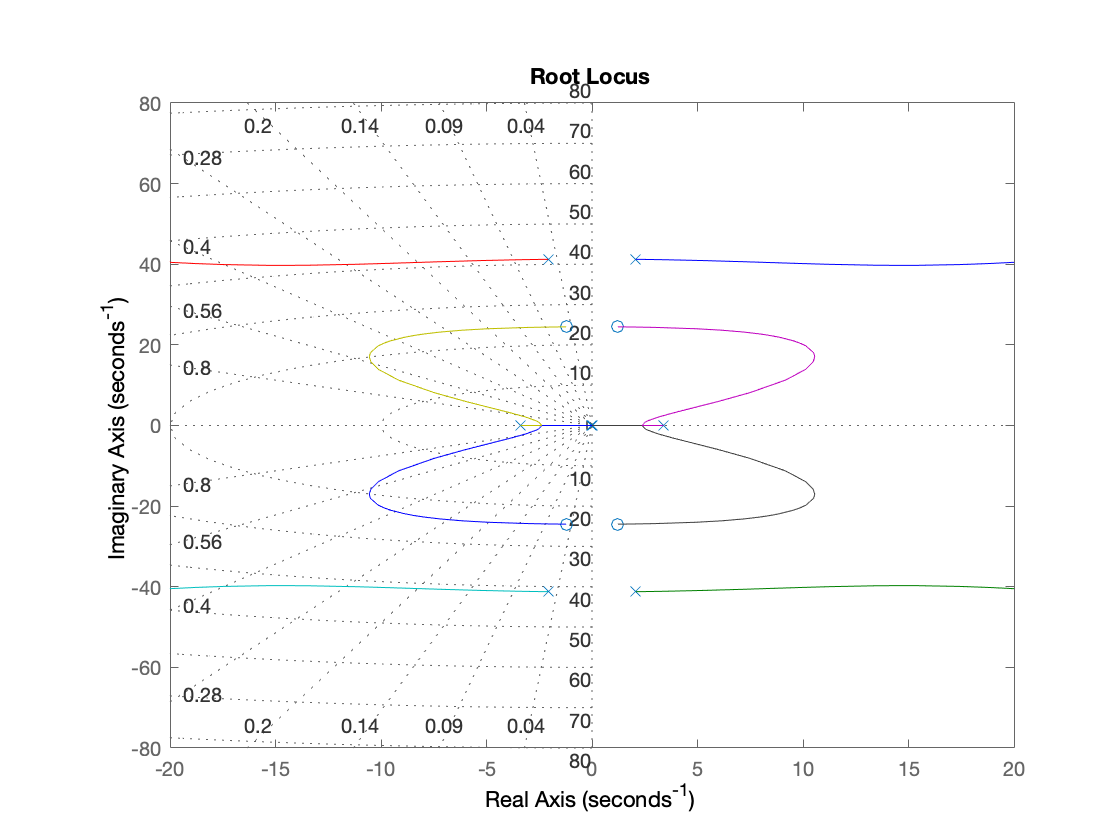

% G(s), G(-s)
lqr_app.sysG = ss(state_space.A,state_space.B,state_space.C,0);
lqr_app.sysGp = ss(-state_space.A,-state_space.B,state_space.C,0);

% Eigs has to have Re <= sigma, -phi <= Angle <= phi
lqr_app.sigma = -3/pctrl.ts;
lqr_app.phi = eig.phi;

% Root locus of 1/r*G(s)*G(-s)
figure
rlocus(lqr_app.sysG*lqr_app.sysGp);
grid on;
xlim([-20,20]);
ylim([-80,80]);

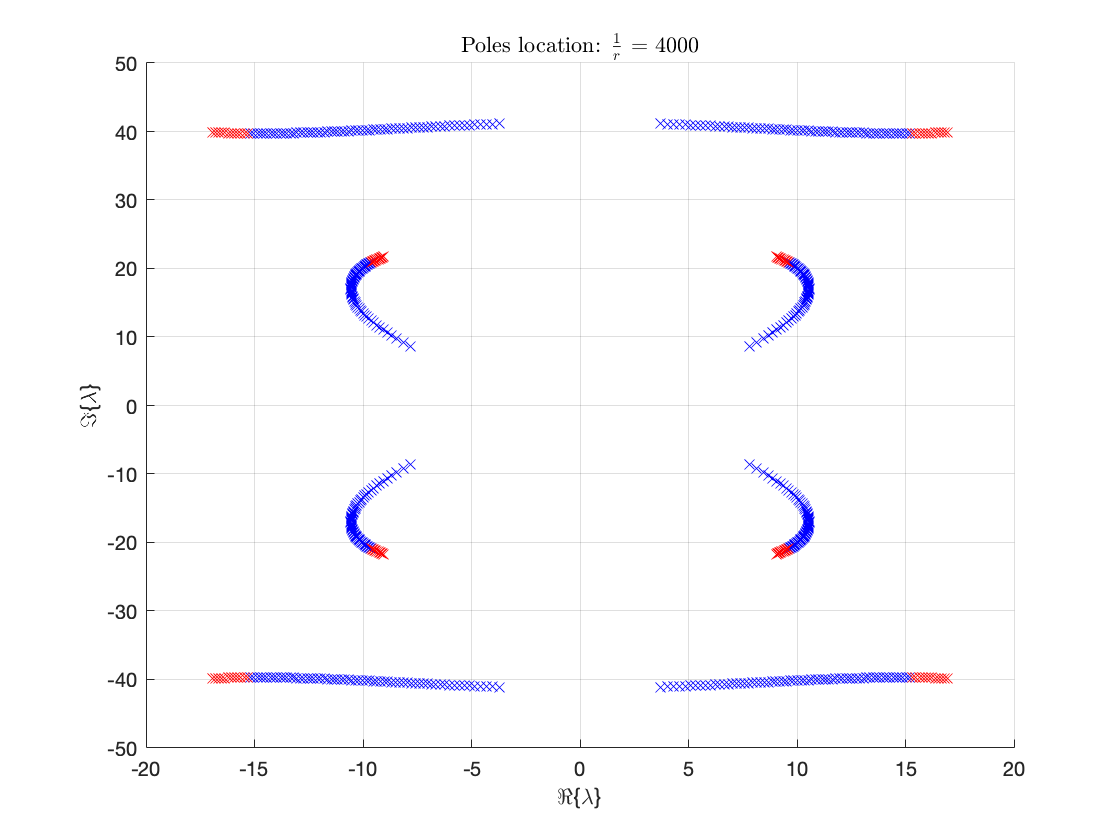

% Plot root locus poles
h = 1;
r_inv_set = zeros(1,3500);
figure;
hold on;
grid on;
xlabel('\Re\{\lambda\}');
ylabel('\Im\{\lambda\}');
poles_notSat = [];
poles_sat = [];
for r_inv = (200:50:5500)
    eigs_for_r = transpose(rlocus(lqr_app.sysG*lqr_app.sysGp,r_inv));
    count = 0;
    for e = eigs_for_r 
        if (real(e) >= -lqr_app.sigma && angle(e) <= lqr_app.phi && angle(e) >= -lqr_app.phi)
            count = count + 1;
        end
    end
    if (count == 4)
        plot(real(eigs_for_r), imag(eigs_for_r), 'rx');
        r_inv_set(h) = r_inv;
        h = h + 1;
    else
        plot(real(eigs_for_r), imag(eigs_for_r), 'bx');
    end
    title(['Poles location: $\frac{1}{r}$ = ', num2str(r_inv)], 'Interpreter', 'latex');
    pause(0.1);
end

% Extract one "RED" set of eigenvalues (middle one)
lqr_app.eigs = rlocus(lqr_app.sysG*lqr_app.sysGp,r_inv_set(round(h/2))); 

% Extract the corrresponding r
lqr_app.r = 1/r_inv_set(round(h/2));
%lqr_app.r = 1/3414;

% State-feedback K
lqr_app.K = lqr(lqr_app.sysG, transpose(state_space.C)*state_space.C, lqr_app.r);

## 2.4.2

#### Simulations results [50°] 

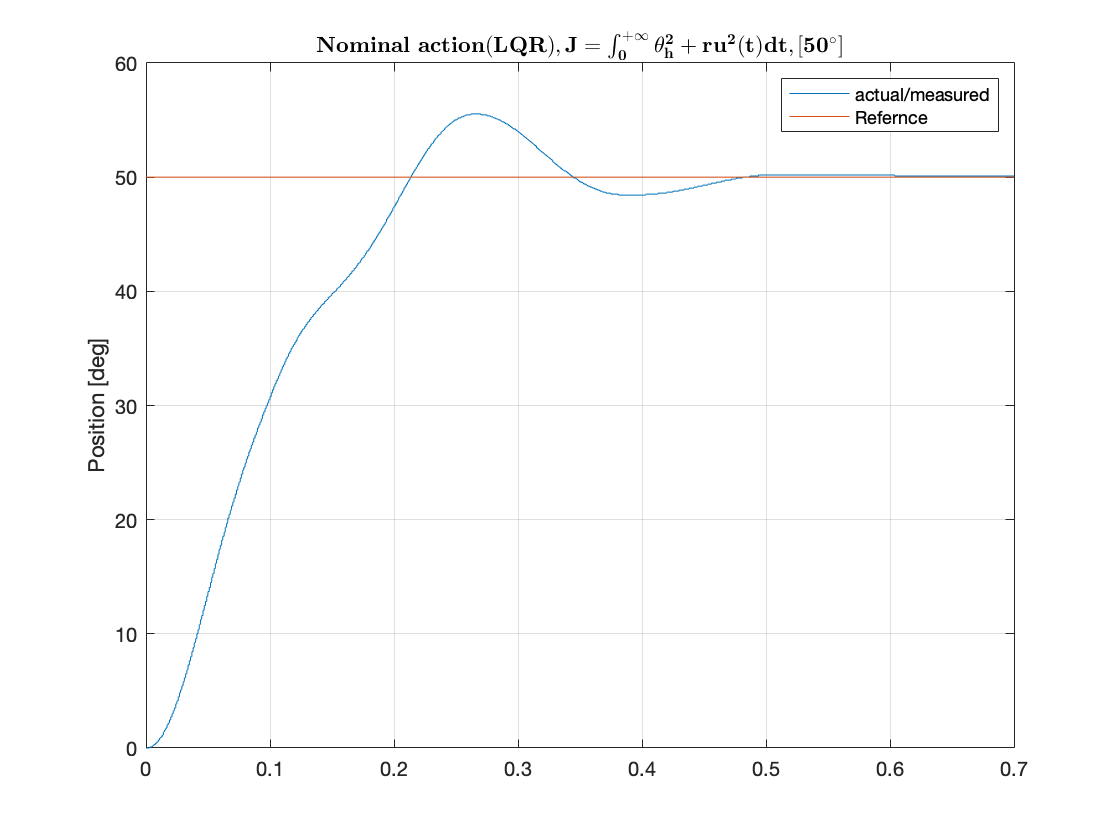

% Set parameters
set_param('SS_eig_LQR', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '0.7');
% Step
set_param('SS_eig_LQR/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('SS_eig_LQR/Enable Integral','Value','0'); % Nominal action ON
set_param('SS_eig_LQR/State-space Controller/Input feedforward gain','gain','nominal.N_u'); % Input feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedforward gain','gain','nominal.N_x'); % State feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','lqr_app.K'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','0'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position
lqr_app.Ref = simres.signals(1).values(:,2); % Reference


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
hold on;
plot(lqr_app.t, lqr_app.Ref);
ylabel('Position [deg]');
ylim([0,60]);
grid on;
title('$\bf{ Nominal \ action (LQR), J = \int_0^{+\infty} {\theta_h^2 + ru^2(t)dt}, [50^{\circ}]}$', 'Interpreter',"latex");
legend('actual/measured', 'Refernce');

## 2.4.3 LQR, $\bf{J = \int_0^{+\infty} {x^T(t)Qx(t) + ru^2(t)dt}}$

% Q,r using Bryson's rule
lqr_app.r_new = 1/100;
lqr_app.Q_diag_elem = [1/(0.3*50*deg2rad)^2 1/(pi/36)^2 0 0];
lqr_app.Q_new = diag(lqr_app.Q_diag_elem);

% State-feedback K
lqr_app.K_new = lqr(lqr_app.sysG, lqr_app.Q_new, lqr_app.r_new);

## 2.4.4

#### Simulations results [50°] 

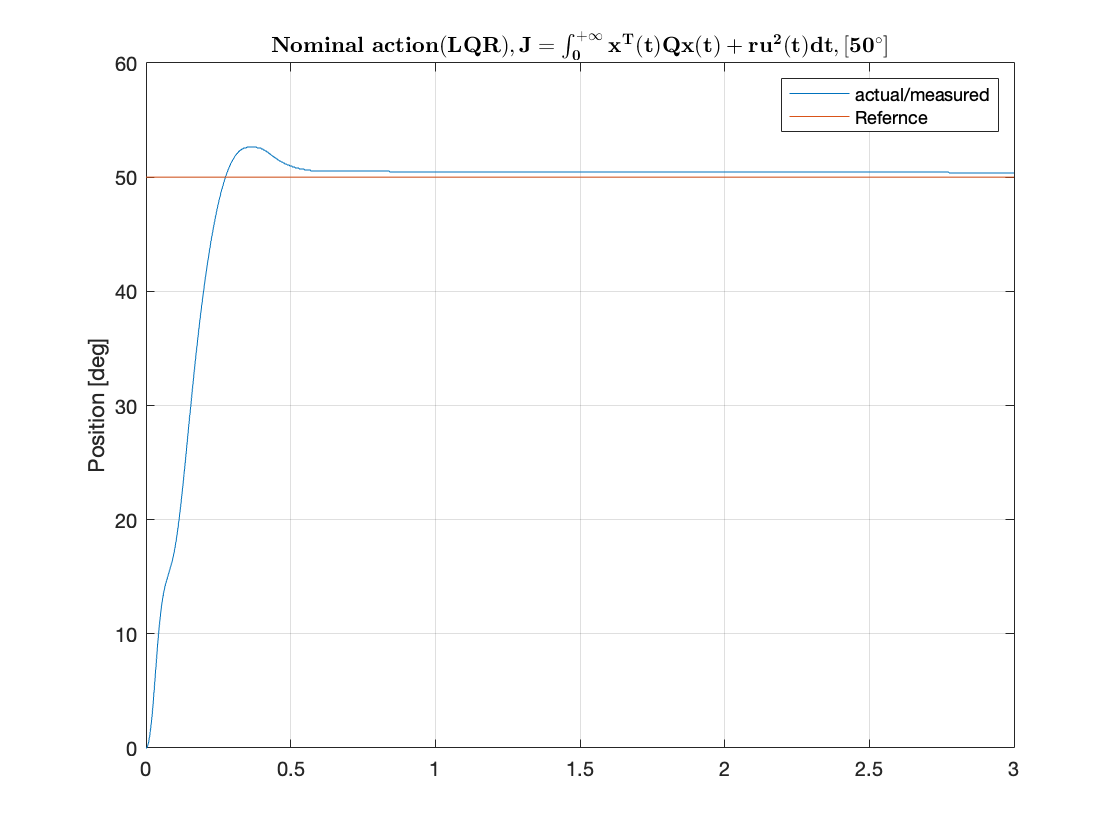

% Set parameters
set_param('SS_eig_LQR', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
% Step
set_param('SS_eig_LQR/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('SS_eig_LQR/Enable Integral','Value','0'); % Nominal action ON
set_param('SS_eig_LQR/State-space Controller/Input feedforward gain','gain','nominal.N_u'); % Input feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedforward gain','gain','nominal.N_x'); % State feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','lqr_app.K_new'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','0'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position
lqr_app.Ref = simres.signals(1).values(:,2); % Reference


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
hold on;
plot(lqr_app.t, lqr_app.Ref);
ylabel('Position [deg]');
ylim([0,60]);
grid on;
title('$\bf{ Nominal \ action (LQR), J = \int_0^{+\infty} {x^T(t)Qx(t) + ru^2(t)dt}, [50^{\circ}]}$', 'Interpreter',"latex");

legend('actual/measured', 'Refernce');

# INTEGRAL [OPTIONAL]

## 2.4.5 LQR, $\bf{J = \int_0^{+\infty} {x_i^2(t) + ru^2(t)dt}}$

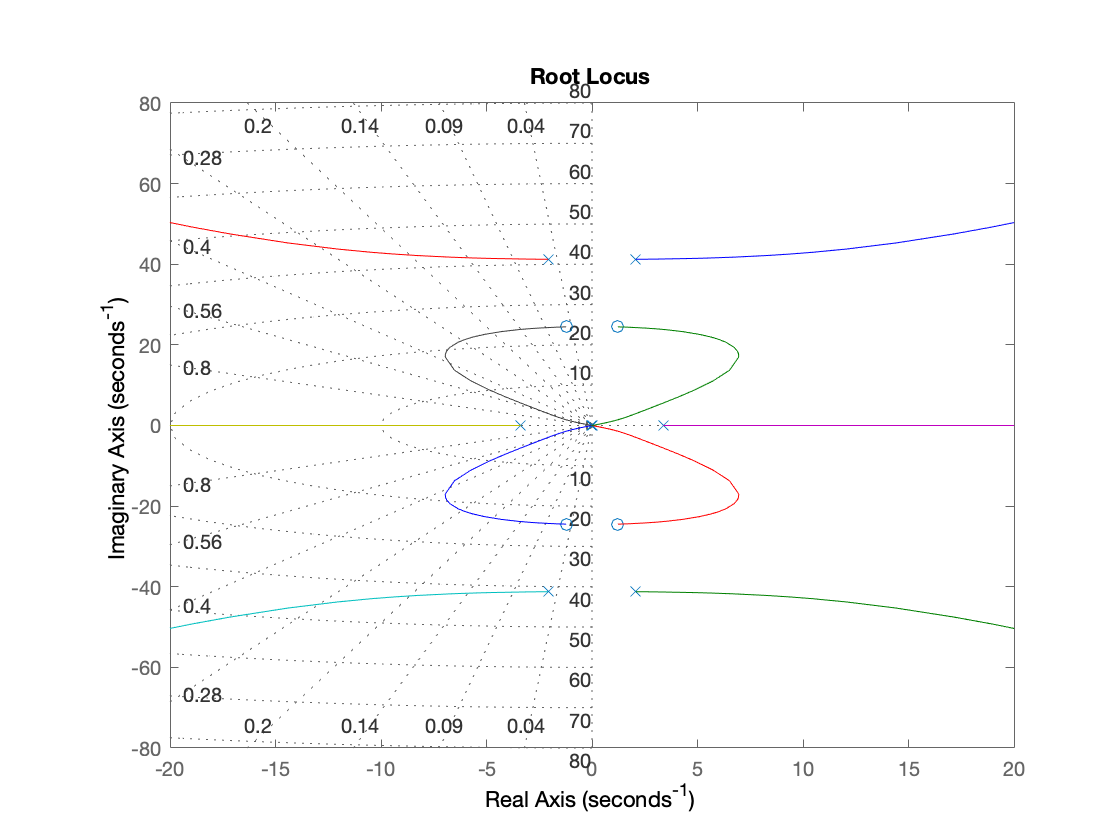

% Augmented state space Ae, Be, Ce
state_space_int.Ae = [0 state_space.C;[0;0;0;0] state_space.A];
state_space_int.Be = [0;state_space.B];
state_space_int.Ce = [1 0 0 0 0];

% Ge(s), Ge(-s)
lqr_app_int.sysGe = ss(state_space_int.Ae,state_space_int.Be,state_space_int.Ce,0);
lqr_app_int.sysGep = ss(-state_space_int.Ae,-state_space_int.Be,state_space_int.Ce,0);

% Eigs has to have Re <= sigma, Angle
lqr_app_int.sigma = -3/pctrl.ts;
lqr_app_int.phi = eig.phi;

% Root locus of 1/r*Ge(s)*Ge(-s)
figure
rlocus(lqr_app_int.sysGe*lqr_app_int.sysGep);
grid on;
xlim([-20,20]);
ylim([-80,80]);

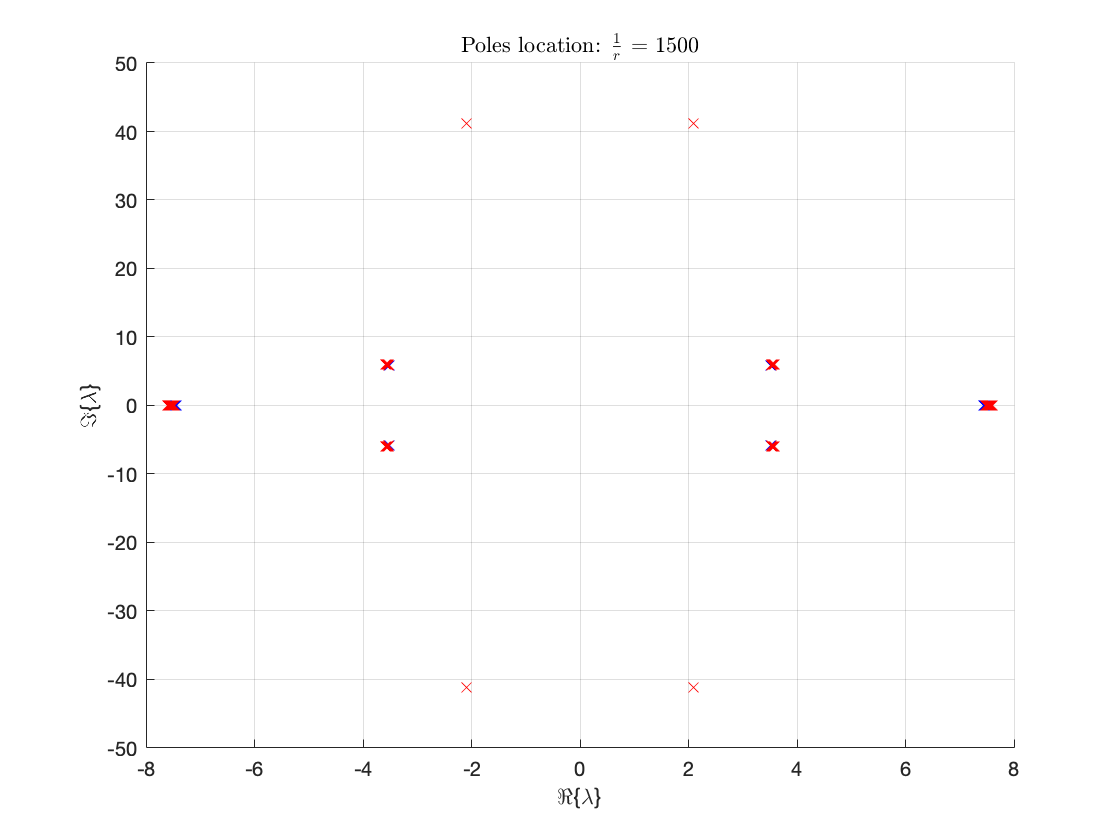

% Plot root locus poles
h = 1;
r_inv_set = zeros(1,3500);
figure;
hold on;
grid on;
xlabel('\Re\{\lambda\}');
ylabel('\Im\{\lambda\}');
poles_notSat = [];
poles_sat = [];
for r_inv = (1300:1:1500)
    eigs_for_r = transpose(rlocus(lqr_app_int.sysGe*lqr_app_int.sysGep,r_inv));
    count = 0;
    for e = eigs_for_r 
        if (real(e) >= -lqr_app_int.sigma && angle(e) <= lqr_app_int.phi && angle(e) >= -lqr_app_int.phi)
            count = count + 1;
        end
    end
    if (count == 3)
        plot(real(eigs_for_r), imag(eigs_for_r), 'rx');
        r_inv_set(h) = r_inv;
        h = h + 1;
    else
        plot(real(eigs_for_r), imag(eigs_for_r), 'bx');
    end
    title(['Poles location: $\frac{1}{r}$ = ', num2str(r_inv)], 'Interpreter', 'latex');
    pause(0.1);
end

% Extract the corresponding r
lqr_app_int.r = 1/1370;

% State-feedback Ke
lqr_app_int.Ke = lqr(lqr_app_int.sysGe, transpose(state_space_int.Ce)*state_space_int.Ce, lqr_app_int.r);
lqr_app_int.Ki = lqr_app_int.Ke(1);
lqr_app_int.K = lqr_app_int.Ke(1,2:5);

## 2.4.6

#### Simulations results [50°] 

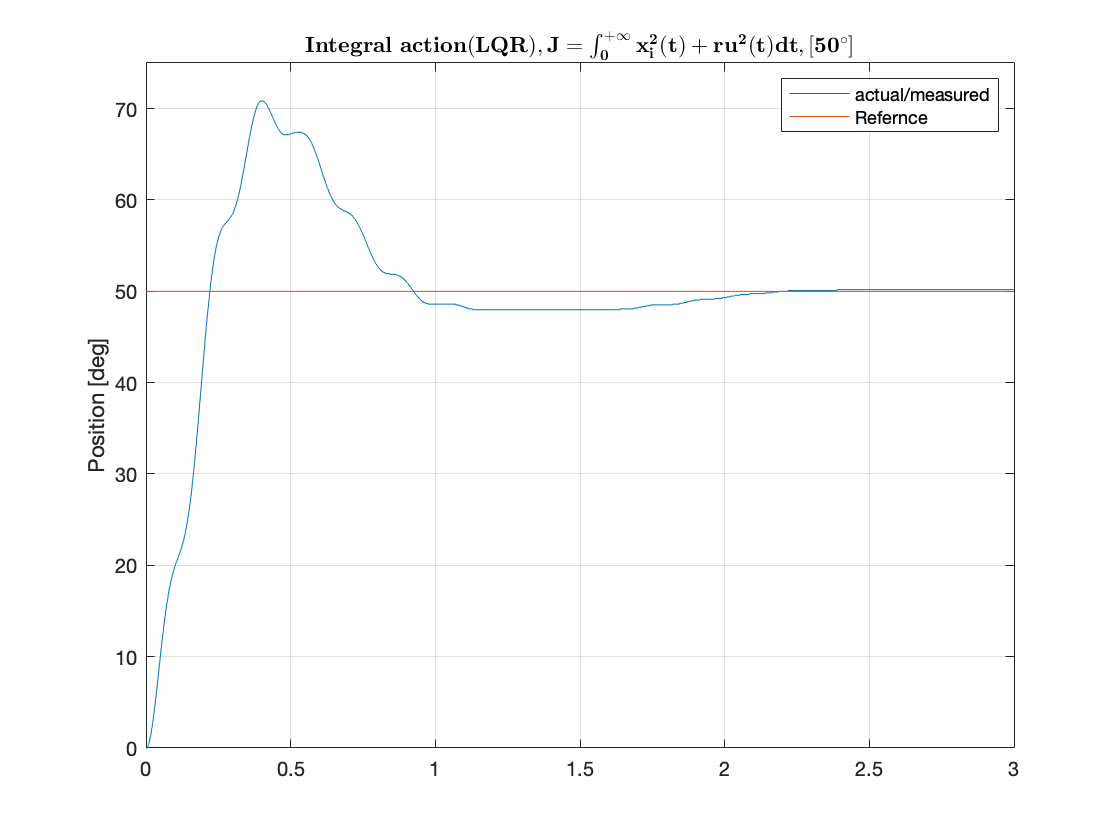

% Set parameters
set_param('SS_eig_LQR', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
% Step
set_param('SS_eig_LQR/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('SS_eig_LQR/Enable Integral','Value','1'); % Integral action ON
set_param('SS_eig_LQR/State-space Controller/Input feedforward gain','gain','nominal.N_u'); % Input feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedforward gain','gain','nominal.N_x'); % State feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','lqr_app_int.K'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','lqr_app_int.Ki'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position
lqr_app.Ref = simres.signals(1).values(:,2); % Reference


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
hold on;
plot(lqr_app.t, lqr_app.Ref);
ylabel('Position [deg]');
ylim([0,75]);
grid on;
title('$\bf{ Integral \ action (LQR), J = \int_0^{+\infty} {x_i^2(t) + ru^2(t)dt}, [50^{\circ}]}$', 'Interpreter',"latex");

legend('actual/measured', 'Refernce');

## 2.4.7 LQR, $\bf{J = \int_0^{+\infty} {x_e(t)Qx_e^T(t) + ru^2(t)dt}}$

% Q1, Q2, Q3, Q4, Q5
lqr_app_int.Q1 = [1/100 0 0 0 0; 0 1/((0.3*50*deg2rad)^2) 0 0 0; 0 0 1/((pi/36)^2) 0 0;0 0 0 0 0;0 0 0 0 0];
lqr_app_int.Q2 = [1/10 0 0 0 0; 0 1/((0.3*50*deg2rad)^2) 0 0 0; 0 0 1/((pi/36)^2) 0 0;0 0 0 0 0;0 0 0 0 0];
lqr_app_int.Q3 = [1 0 0 0 0; 0 1/((0.3*50*deg2rad)^2) 0 0 0; 0 0 1/((pi/36)^2) 0 0;0 0 0 0 0;0 0 0 0 0];
lqr_app_int.Q4 = [10 0 0 0 0; 0 1/((0.3*50*deg2rad)^2) 0 0 0; 0 0 1/((pi/36)^2) 0 0;0 0 0 0 0;0 0 0 0 0];
lqr_app_int.Q5 = [100 0 0 0 0; 0 1/((0.3*50*deg2rad)^2) 0 0 0; 0 0 1/((pi/36)^2) 0 0;0 0 0 0 0;0 0 0 0 0];

% State-feedback Ke1
lqr_app_int.Ke_new1 = lqr(lqr_app_int.sysGe, lqr_app_int.Q1, 1/100);
lqr_app_int.K1i = lqr_app_int.Ke_new1(1);
lqr_app_int.K1 = lqr_app_int.Ke_new1(1,2:5);

% State-feedback Ke12
lqr_app_int.Ke_new2 = lqr(lqr_app_int.sysGe, lqr_app_int.Q2, 1/100);
lqr_app_int.K2i = lqr_app_int.Ke_new2(1);
lqr_app_int.K2= lqr_app_int.Ke_new2(1,2:5);

% State-feedback Ke3
lqr_app_int.Ke_new3 = lqr(lqr_app_int.sysGe, lqr_app_int.Q3, 1/100);
lqr_app_int.K3i = lqr_app_int.Ke_new3(1);
lqr_app_int.K3 = lqr_app_int.Ke_new3(1,2:5);

% State-feedback Ke4
lqr_app_int.Ke_new4 = lqr(lqr_app_int.sysGe, lqr_app_int.Q4, 1/100);
lqr_app_int.K4i = lqr_app_int.Ke_new4(1);
lqr_app_int.K4 = lqr_app_int.Ke_new4(1,2:5);

% State-feedback Ke5
lqr_app_int.Ke_new5 = lqr(lqr_app_int.sysGe, lqr_app_int.Q5, 1/100);
lqr_app_int.K5i = lqr_app_int.Ke_new5(1);
lqr_app_int.K5 = lqr_app_int.Ke_new5(1,2:5);

## 2.4.8

#### Simulations results [50°] 

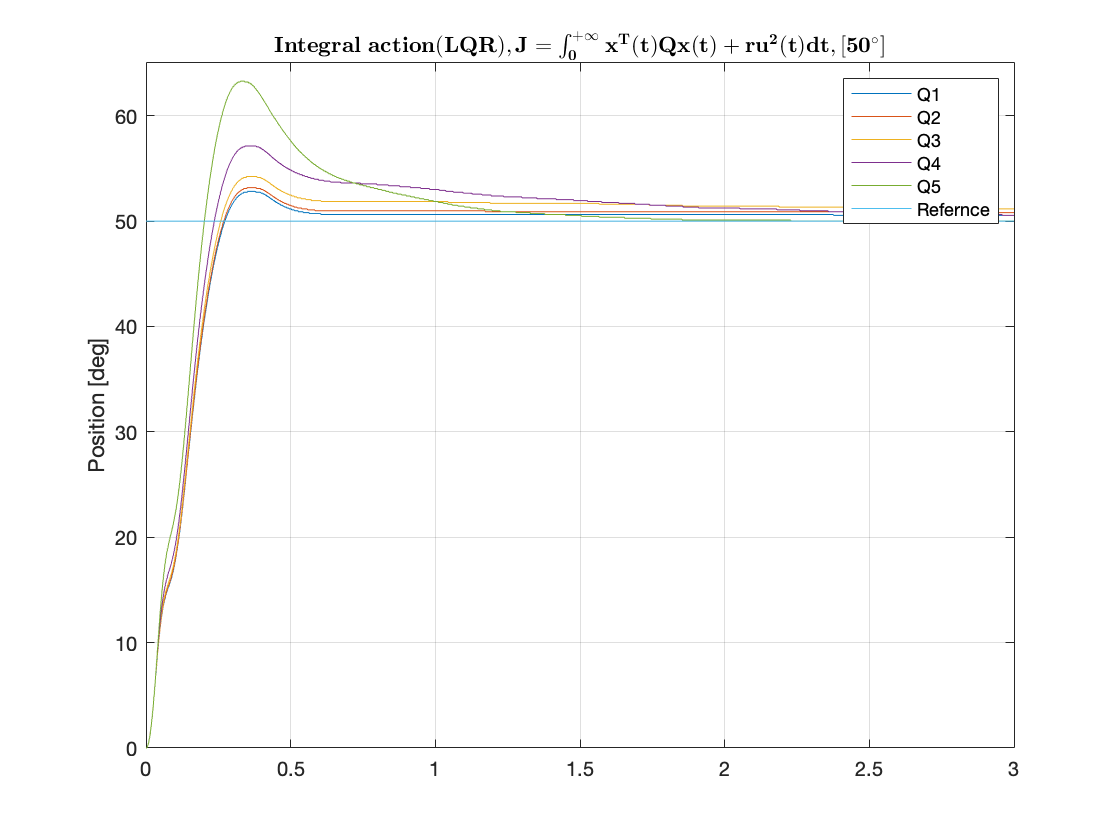

% Set parameters
set_param('SS_eig_LQR', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
% Step
set_param('SS_eig_LQR/Step','Time','0','Before','0','After','50');

% State-space Controller (Q1)
set_param('SS_eig_LQR/Enable Integral','Value','1'); % Integral action ON
set_param('SS_eig_LQR/State-space Controller/Input feedforward gain','gain','nominal.N_u'); % Input feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedforward gain','gain','nominal.N_x'); % State feedforward gain
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','lqr_app_int.K1'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','lqr_app_int.K1i'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
lqr_app.t1 = simres.time; % Time vector 
lqr_app.thh1 = simres.signals(1).values(:,1); % Hub position
lqr_app.Ref = simres.signals(1).values(:,2); % Reference

% State-space Controller (Q2)
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','lqr_app_int.K2'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','lqr_app_int.K2i'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
lqr_app.t2 = simres.time; % Time vector
lqr_app.thh2 = simres.signals(1).values(:,1); % Hub position

% State-space Controller (Q3)
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','lqr_app_int.K3'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','lqr_app_int.K3i'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
lqr_app.t3 = simres.time; % Time vector
lqr_app.thh3 = simres.signals(1).values(:,1); % Hub position

% State-space Controller (Q4)
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','lqr_app_int.K4'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','lqr_app_int.K4i'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
lqr_app.t4 = simres.time; % Time vector
lqr_app.thh4 = simres.signals(1).values(:,1); % Hub position

% State-space Controller (Q5)
set_param('SS_eig_LQR/State-space Controller/State feedback gain','gain','lqr_app_int.K5'); % State feedback gain
set_param('SS_eig_LQR/State-space Controller/Ki','Gain','lqr_app_int.K5i'); % Integral gain

% Run simulation
sim('SS_eig_LQR');

% Extract simulation results
lqr_app.t5 = simres.time; % Time vector
lqr_app.thh5 = simres.signals(1).values(:,1); % Hub position


% Plot simulation results
figure
plot(lqr_app.t1, lqr_app.thh1);
hold on;
plot(lqr_app.t2, lqr_app.thh2);
hold on;
plot(lqr_app.t3, lqr_app.thh3);
hold on;
plot(lqr_app.t4, lqr_app.thh4);
hold on;
plot(lqr_app.t5, lqr_app.thh5);
hold on;
plot(lqr_app.t1, lqr_app.Ref);
ylabel('Position [deg]');
ylim([0,65]);
grid on;
title('$\bf{ Integral \ action (LQR), J = \int_0^{+\infty} {x^T(t)Qx(t) + ru^2(t)dt}, [50^{\circ}]}$', 'Interpreter',"latex");
legend('Q1', 'Q2', 'Q3', 'Q4', 'Q5', 'Refernce');

# Frequency shaped LQR

# NOMINAL

## 2.4.9-2.4.10

% wn, zeta of the pair of complex conjugate poles
[wn_tot, zeta_tot] = damp(ss(state_space.A, state_space.B, state_space.C, 0));
[z,p,k] = ss2zp(state_space.A, state_space.B, state_space.C, 0);
wn = wn_tot(3);
zeta = zeta_tot(3);

% Frequency resonance
FS_LQR.w0 = wn*sqrt(1-zeta^2);


$$\bf{J_{FS} = \int_0^{+\infty} {\pmatrix{x_A^T(t) & u^T(t)}\pmatrix{Q_A & 0 \cr 0 & R_A} \pmatrix{x_A(t) \cr u(t)}dt }}, \ \ \ Q_A = \left( \begin{array}{ccccc} \frac{1}{\bar{\theta_h}^2} & 0 & 0 & 0 \vert & 0 & 0 \\ 0 & 0 & 0 & 0 \vert & 0 & 0  \\  0 & 0 & 0 & 0 \vert & 0 & 0  \\
 0 & 0 & 0 & 0 \vert & 0 & 0  \\ 
\hline  0 & 0 & 0 & 0 \vert & q_{22}w_0^4 & 0  \\  0 & 0 & 0 & 0 \vert & 0 & 0  \\
 \end{array} \right), \ \ R_A = \frac{1}{\bar{\theta_{u}}^2} \\
s.t.\\ \  \Sigma_A : \dot{x_A} =  A_Ax_A + B_Au
$$


## 
$$\bf{q_{22}} = 0.01$$


% q22(w)
FS_LQR.q22 = 0.01;

% Aq', Bq', Cq', Dq'
FS_LQR.Aq_p = [0 1;-FS_LQR.w0^2 0];
FS_LQR.Bq_p = [0;1];
FS_LQR.Cq_p = [sqrt(FS_LQR.q22)*FS_LQR.w0^2 0];
FS_LQR.Dq_p = 0;

% Aq, Bq, Cq, Dq
FS_LQR.Aq = FS_LQR.Aq_p;
FS_LQR.Bq = [[0;0] FS_LQR.Bq_p [0 0;0 0]];
FS_LQR.Cq = [0 0;FS_LQR.Cq_p;[0 0;0 0]];
FS_LQR.Dq = diag([1/(5*pi/180) FS_LQR.Dq_p 0 0]);

% Aa, Ba, Ca, Da
FS_LQR.Aa = [state_space.A [0 0;0 0;0 0;0 0];FS_LQR.Bq FS_LQR.Aq];
FS_LQR.Ba = [state_space.B;[0;0]];
FS_LQR.Ca = [state_space.C 0 0];
FS_LQR.Da = 0;

% Qa, Na, Ra
FS_LQR.Qa001 = [transpose(FS_LQR.Dq)*FS_LQR.Dq transpose(FS_LQR.Dq)*FS_LQR.Cq;transpose(FS_LQR.Cq)*FS_LQR.Dq transpose(FS_LQR.Cq)*FS_LQR.Cq];
FS_LQR.Na = [0;0;0;0;0;0];
FS_LQR.Ra = 0.01;

% Ka
FS_LQR.Ka = lqr(FS_LQR.Aa, FS_LQR.Ba, FS_LQR.Qa001, FS_LQR.Ra);

% Nxa, Nu
[FS_LQR.Na] = linsolve([FS_LQR.Aa FS_LQR.Ba; FS_LQR.Ca FS_LQR.Da], [0;0;0;0;0;0;1]);
FS_LQR.Nxa = FS_LQR.Na(1:6,1); 
FS_LQR.Nu = FS_LQR.Na(7,1); 


#### Simulations results [50°] 

% Open Simulink
open_system('Simulink/FS.slx');
% Set parameters
set_param('FS', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
% Step
set_param('FS/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('FS/Enable Integral','Value','0'); % Nominal action ON
set_param('FS/State-space Controller/Input feedforward gain','gain','FS_LQR.Nu'); % Input feedforward gain
set_param('FS/State-space Controller/State feedforward gain','gain','FS_LQR.Nxa'); % State feedforward gain
set_param('FS/State-space Controller/State feedback gain','gain','FS_LQR.Ka'); % State feedback gain
set_param('FS/State-space Controller/Ki','gain','0'); % Integrator

% Run simulation
sim('FS');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position

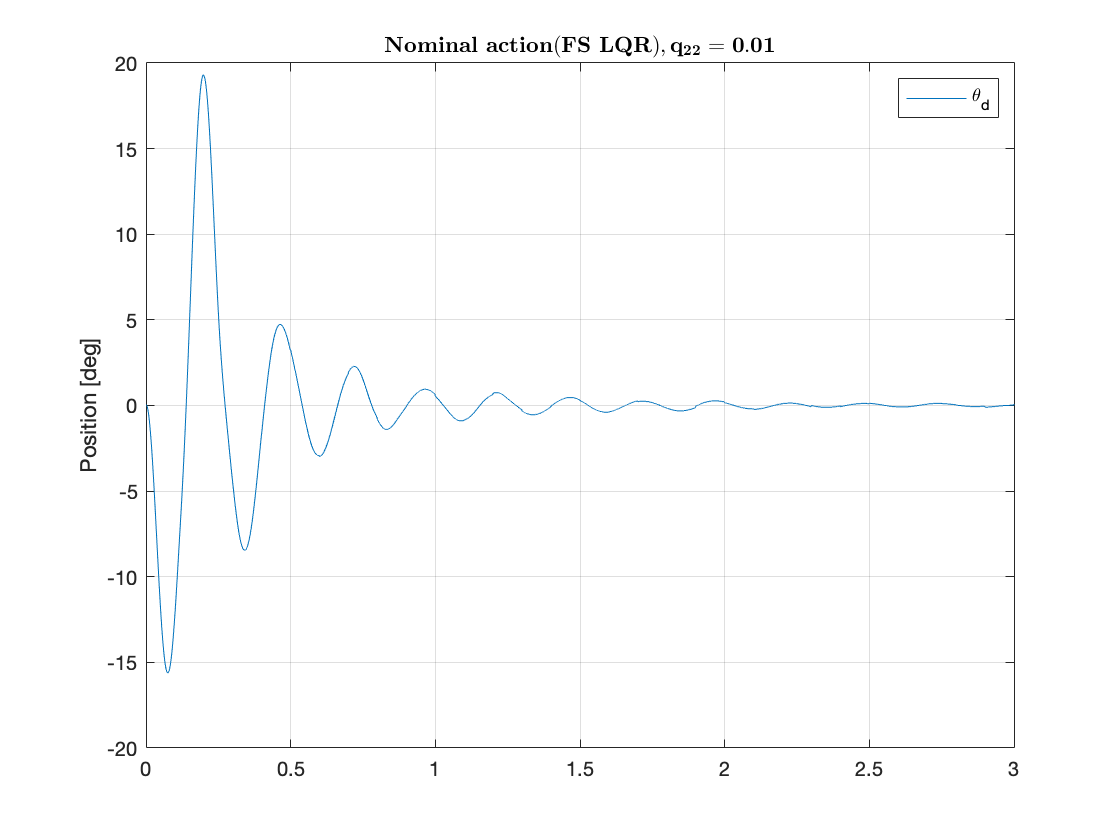


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
ylabel('Position [deg]');
ylim([-20,20]);
grid on;
title('$\bf{ Nominal \ action (FS \ LQR), q_{22} = 0.01}$', 'Interpreter',"latex");
legend('\theta_d');

## 
$$\bf{q_{22}} = 1$$


% q22(w)
FS_LQR.q22 = 1;

% Aq', Bq', Cq', Dq'
FS_LQR.Aq_p = [0 1;-FS_LQR.w0^2 0];
FS_LQR.Bq_p = [0;1];
FS_LQR.Cq_p = [sqrt(FS_LQR.q22)*FS_LQR.w0^2 0];
FS_LQR.Dq_p = 0;

% Aq, Bq, Cq, Dq
FS_LQR.Aq = FS_LQR.Aq_p;
FS_LQR.Bq = [[0;0] FS_LQR.Bq_p [0 0;0 0]];
FS_LQR.Cq = [0 0;FS_LQR.Cq_p;[0 0;0 0]];
FS_LQR.Dq = diag([1/(5*pi/180) FS_LQR.Dq_p 0 0]);

% Aa, Ba, Ca, Da
FS_LQR.Aa = [state_space.A [0 0;0 0;0 0;0 0];FS_LQR.Bq FS_LQR.Aq];
FS_LQR.Ba = [state_space.B;[0;0]];
FS_LQR.Ca = [state_space.C 0 0];
FS_LQR.Da = 0;

% Qa, Na, Ra
FS_LQR.Qa1 = [transpose(FS_LQR.Dq)*FS_LQR.Dq transpose(FS_LQR.Dq)*FS_LQR.Cq;transpose(FS_LQR.Cq)*FS_LQR.Dq transpose(FS_LQR.Cq)*FS_LQR.Cq];
FS_LQR.Na = [0;0;0;0;0;0];
FS_LQR.Ra = 0.01;

% Ka
FS_LQR.Ka = lqr(FS_LQR.Aa, FS_LQR.Ba, FS_LQR.Qa1, FS_LQR.Ra);

% Nxa, Nu
[FS_LQR.Na] = linsolve([FS_LQR.Aa FS_LQR.Ba; FS_LQR.Ca FS_LQR.Da], [0;0;0;0;0;0;1]);
FS_LQR.Nxa = FS_LQR.Na(1:6,1); 
FS_LQR.Nu = FS_LQR.Na(7,1); 


#### Simulations results [50°] 

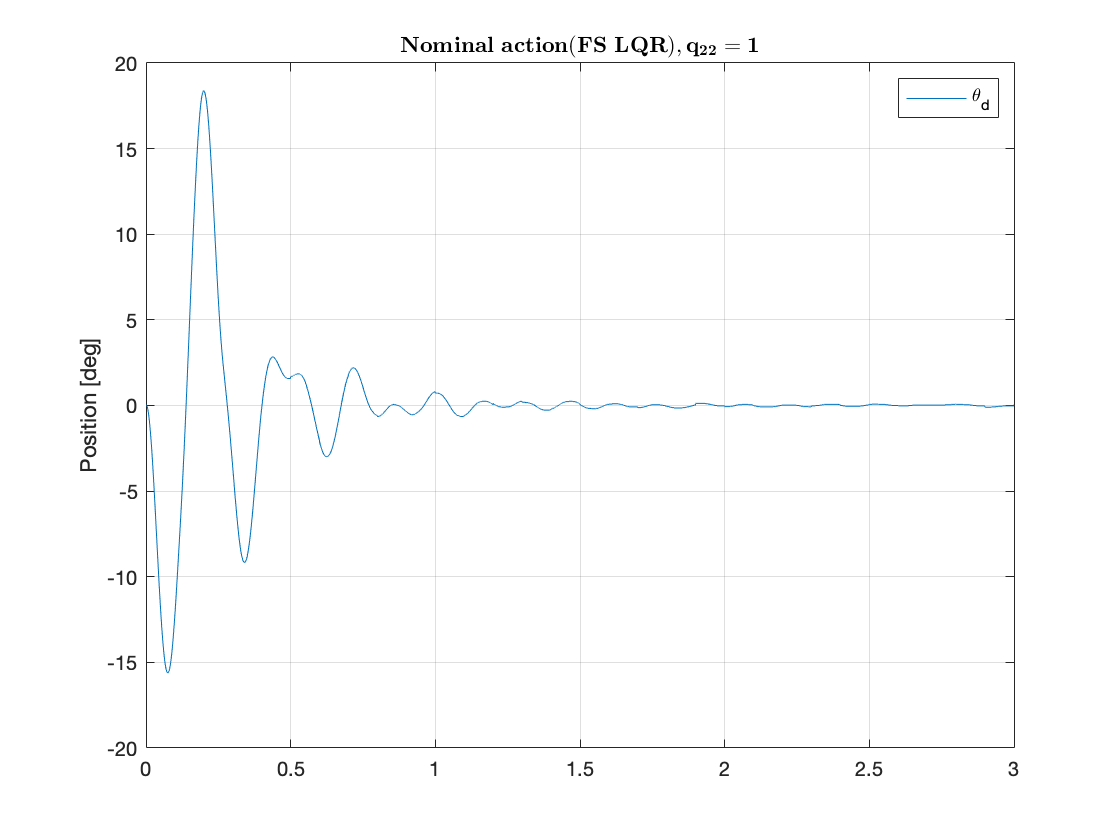

% Set parameters
set_param('FS', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
% Step
set_param('FS/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('FS/Enable Integral','Value','0'); % Nominal action ON
set_param('FS/State-space Controller/Input feedforward gain','gain','FS_LQR.Nu'); % Input feedforward gain
set_param('FS/State-space Controller/State feedforward gain','gain','FS_LQR.Nxa'); % State feedforward gain
set_param('FS/State-space Controller/State feedback gain','gain','FS_LQR.Ka'); % State feedback gain

% Run simulation
sim('FS');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
ylabel('Position [deg]');
ylim([-20,20]);
grid on;
title('$\bf{ Nominal \ action (FS \ LQR), q_{22} = 1}$', 'Interpreter',"latex");
legend('\theta_d');

## 
$$\bf{q_{22}} = 100$$


% q22(w)
FS_LQR.q22 = 100;

% Aq', Bq', Cq', Dq'
FS_LQR.Aq_p = [0 1;-FS_LQR.w0^2 0];
FS_LQR.Bq_p = [0;1];
FS_LQR.Cq_p = [sqrt(FS_LQR.q22)*FS_LQR.w0^2 0];
FS_LQR.Dq_p = 0;

% Aq, Bq, Cq, Dq
FS_LQR.Aq = FS_LQR.Aq_p;
FS_LQR.Bq = [[0;0] FS_LQR.Bq_p [0 0;0 0]];
FS_LQR.Cq = [0 0;FS_LQR.Cq_p;[0 0;0 0]];
FS_LQR.Dq = diag([1/(5*pi/180) FS_LQR.Dq_p 0 0]);

% Aa, Ba, Ca, Da
FS_LQR.Aa = [state_space.A [0 0;0 0;0 0;0 0];FS_LQR.Bq FS_LQR.Aq];
FS_LQR.Ba = [state_space.B;[0;0]];
FS_LQR.Ca = [state_space.C 0 0];
FS_LQR.Da = 0;

% Qa, Na, Ra
FS_LQR.Qa100 = [transpose(FS_LQR.Dq)*FS_LQR.Dq transpose(FS_LQR.Dq)*FS_LQR.Cq;transpose(FS_LQR.Cq)*FS_LQR.Dq transpose(FS_LQR.Cq)*FS_LQR.Cq];
FS_LQR.Na = [0;0;0;0;0;0];
FS_LQR.Ra = 0.01;

% Ka
FS_LQR.Ka = lqr(FS_LQR.Aa, FS_LQR.Ba, FS_LQR.Qa100, FS_LQR.Ra);

% Nxa, Nu
[FS_LQR.Na] = linsolve([FS_LQR.Aa FS_LQR.Ba; FS_LQR.Ca FS_LQR.Da], [0;0;0;0;0;0;1]);
FS_LQR.Nxa = FS_LQR.Na(1:6,1); 
FS_LQR.Nu = FS_LQR.Na(7,1); 


#### Simulations results [50°] 

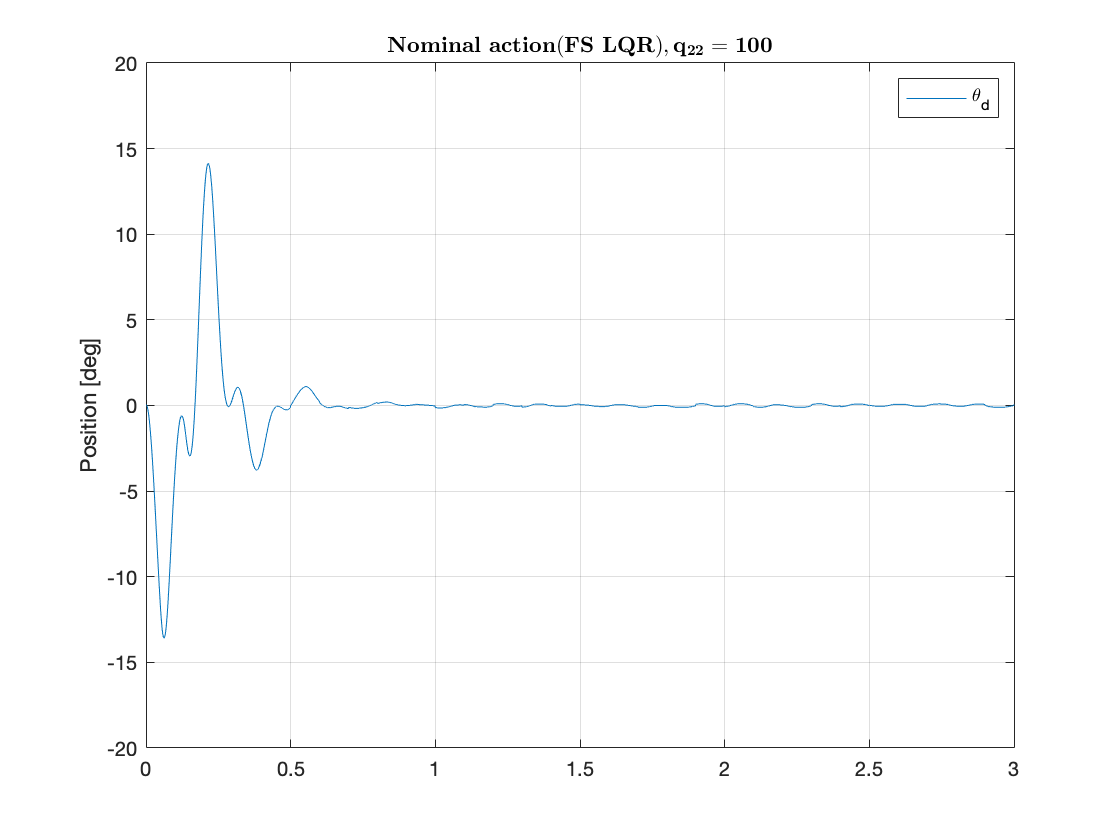

% Set parameters
set_param('FS', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');
% Step
set_param('FS/Step','Time','0','Before','0','After','50');

% State-space Controller
set_param('FS/Enable Integral','Value','0'); % Nominal action ON
set_param('FS/State-space Controller/Input feedforward gain','gain','FS_LQR.Nu'); % Input feedforward gain
set_param('FS/State-space Controller/State feedforward gain','gain','FS_LQR.Nxa'); % State feedforward gain
set_param('FS/State-space Controller/State feedback gain','gain','FS_LQR.Ka'); % State feedback gain

% Run simulation
sim('FS');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
ylabel('Position [deg]');
ylim([-20,20]);
grid on;
title('$\bf{ Nominal \ action (FS \ LQR), q_{22} = 100}$', 'Interpreter',"latex");
legend('\theta_d');

# INTEGRAL

## 2.4.10-2.4.11


$$\bf{J_{FS} = \int_0^{+\infty} {\pmatrix{x_e^T(t) & u^T(t)}\pmatrix{Q_e & 0 \cr 0 & R_e} \pmatrix{x_e(t) \cr u(t)}dt }}, \ \ \ Q_e = \left( \begin{array}{cc} q_I & 0_{1x6} \\ 0_{6x1} & Q_A
 \end{array} \right), \ \ R_e = R_A =  \frac{1}{\bar{\theta_{u}}^2}, \ \ q_I = 10 \\
s.t.\\ \  \Sigma_e : \dot{x_e} =  A_ex_e + B_eu$$


## 
$$\bf{q_{22}} = 0.01$$


% Ae, Be, Ce, De
FS_LQR.Ae = [0 FS_LQR.Ca; [0; 0; 0; 0; 0; 0] FS_LQR.Aa];
FS_LQR.Be = [0; FS_LQR.Ba];
FS_LQR.Ce = [0 FS_LQR.Ca];
FS_LQR.De = 0;

% Qe, Re
FS_LQR.qi = 10;
FS_LQR.Qe = [FS_LQR.qi 0 0 0 0 0 0;[0;0;0;0;0;0] FS_LQR.Qa001];
FS_LQR.Re = FS_LQR.Ra;

% Ke, Kei, Kea
FS_LQR.Ke = lqr(FS_LQR.Ae, FS_LQR.Be, FS_LQR.Qe, FS_LQR.Re);
FS_LQR.Kei = FS_LQR.Ke(1);
FS_LQR.Kea = FS_LQR.Ke(2:7);

#### Simulations results [50°] 

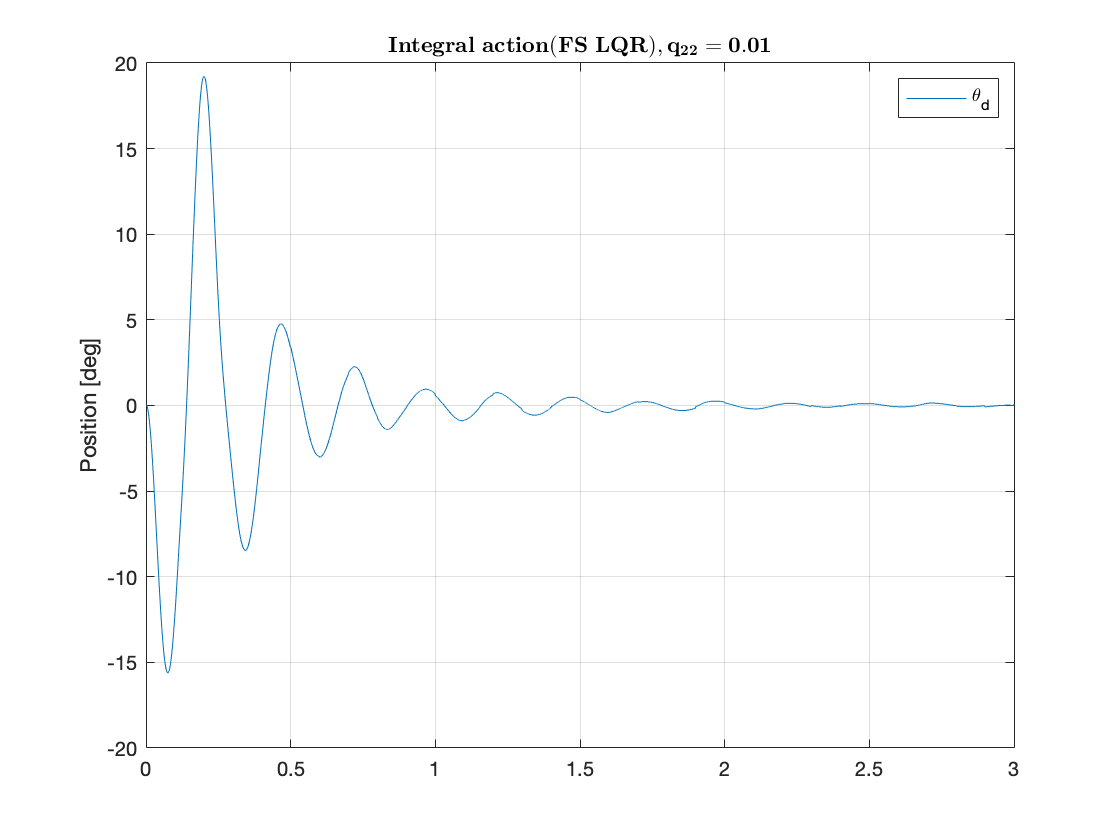

% Set parameters
set_param('FS', ...
    'SolverType', 'Variable-step', ...
    'Solver', 'ode45', ...
    'StopTime', '3');

% State-space Controller
set_param('FS/Enable Integral','Value','1'); % Integral action ON
set_param('FS/State-space Controller/State feedback gain','gain','FS_LQR.Kea'); % State feedback gain
set_param('FS/State-space Controller/Ki','gain','FS_LQR.Kei'); % Integrator

% Run simulation
sim('FS');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
ylabel('Position [deg]');
ylim([-20,20]);
grid on;
title('$\bf{ Integral \ action (FS \ LQR), q_{22} = 0.01}$', 'Interpreter',"latex");
legend('\theta_d');

## 
$$\bf{q_{22}} = 1$$


% Ae, Be, Ce, De
FS_LQR.Ae = [0 FS_LQR.Ca; [0; 0; 0; 0; 0; 0] FS_LQR.Aa];
FS_LQR.Be = [0; FS_LQR.Ba];
FS_LQR.Ce = [0 FS_LQR.Ca];
FS_LQR.De = 0;

% Qe, Re
FS_LQR.qi = 10;
FS_LQR.Qe = [FS_LQR.qi 0 0 0 0 0 0;[0;0;0;0;0;0] FS_LQR.Qa1];
FS_LQR.Re = FS_LQR.Ra;

% Ke, Kei, Kea
FS_LQR.Ke = lqr(FS_LQR.Ae, FS_LQR.Be, FS_LQR.Qe, FS_LQR.Re);
FS_LQR.Kei = FS_LQR.Ke(1);
FS_LQR.Kea = FS_LQR.Ke(2:7);

#### Simulations results [50°] 

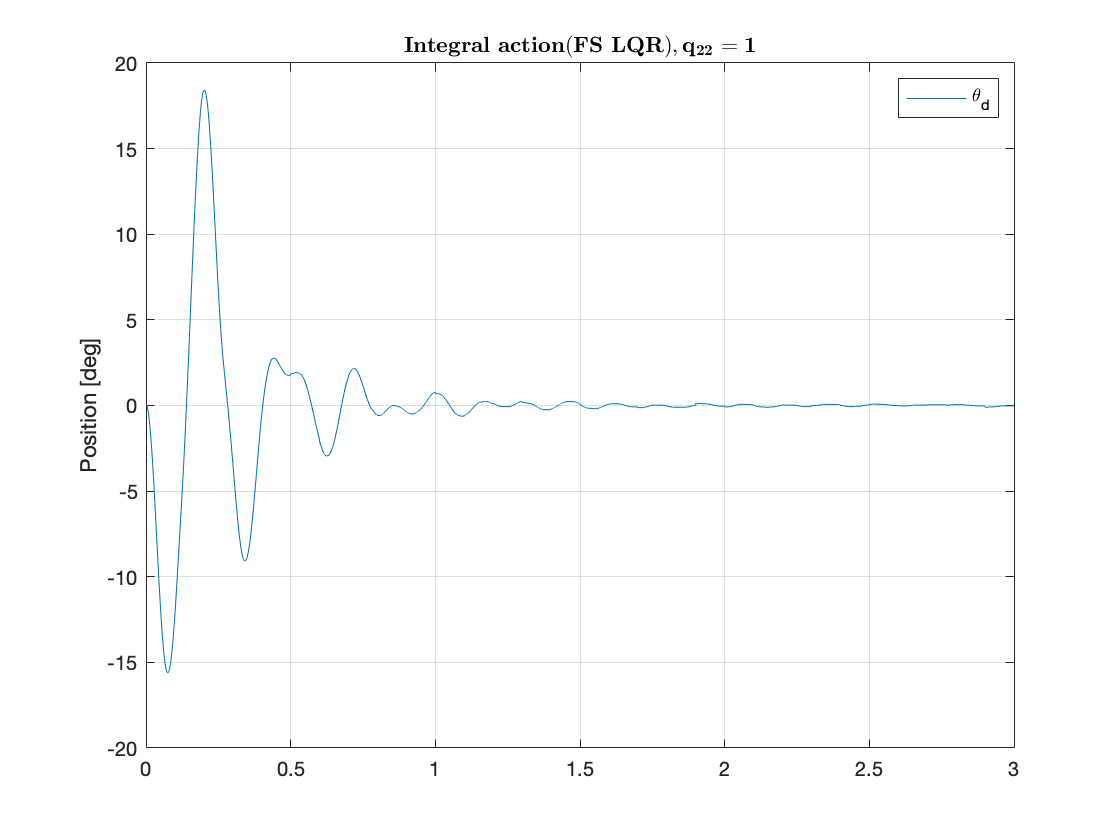

% State-space Controller
set_param('FS/Enable Integral','Value','1'); % Integral action ON
set_param('FS/State-space Controller/State feedback gain','gain','FS_LQR.Kea'); % State feedback gain
set_param('FS/State-space Controller/Ki','gain','FS_LQR.Kei'); % Integrator

% Run simulation
sim('FS');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
ylabel('Position [deg]');
ylim([-20,20]);
grid on;
title('$\bf{ Integral \ action (FS \ LQR), q_{22} = 1}$', 'Interpreter',"latex");
legend('\theta_d');

## 
$$\bf{q_{22}} = 100$$


% Ae, Be, Ce, De
FS_LQR.Ae = [0 FS_LQR.Ca; [0; 0; 0; 0; 0; 0] FS_LQR.Aa];
FS_LQR.Be = [0; FS_LQR.Ba];
FS_LQR.Ce = [0 FS_LQR.Ca];
FS_LQR.De = 0;

% Qe, Re
FS_LQR.qi = 10;
FS_LQR.Qe = [FS_LQR.qi 0 0 0 0 0 0;[0;0;0;0;0;0] FS_LQR.Qa100];
FS_LQR.Re = FS_LQR.Ra;

% Ke, Kei, Kea
FS_LQR.Ke = lqr(FS_LQR.Ae, FS_LQR.Be, FS_LQR.Qe, FS_LQR.Re);
FS_LQR.Kei = FS_LQR.Ke(1);
FS_LQR.Kea = FS_LQR.Ke(2:7);

#### Simulations results [50°] 

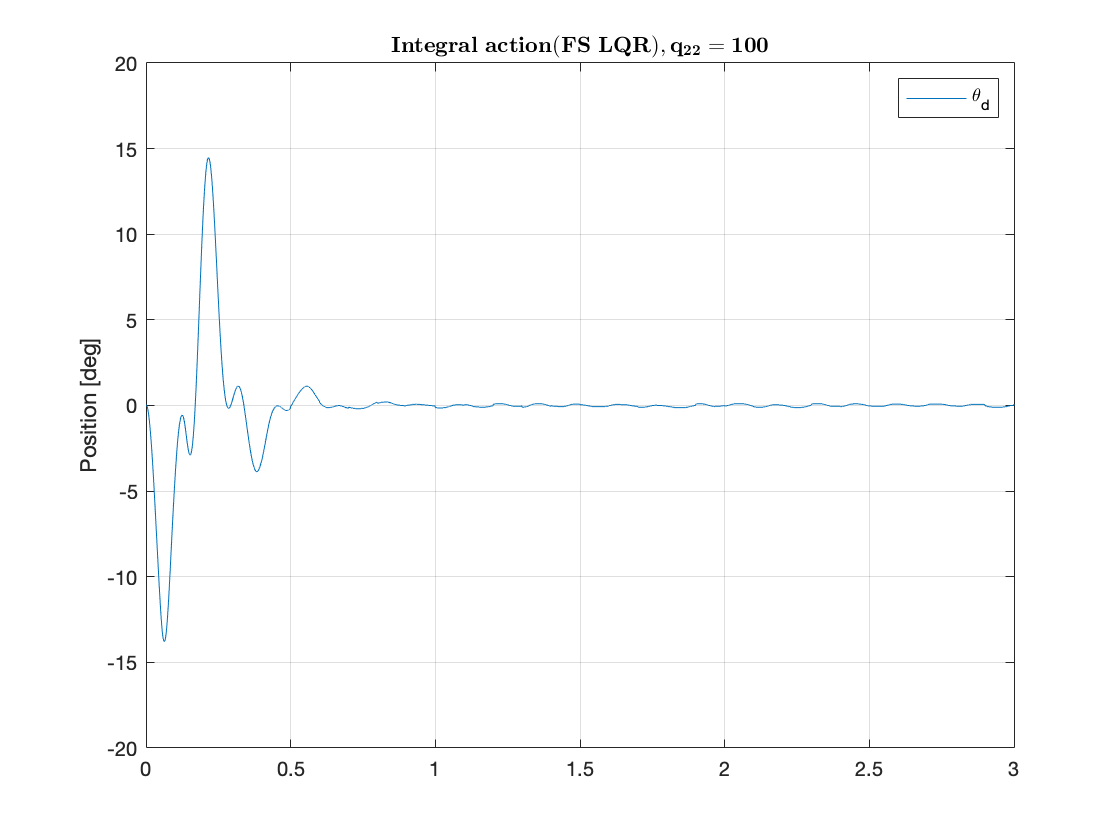

% State-space Controller
set_param('FS/Enable Integral','Value','1'); % Integral action ON
set_param('FS/State-space Controller/State feedback gain','gain','FS_LQR.Kea'); % State feedback gain
set_param('FS/State-space Controller/Ki','gain','FS_LQR.Kei'); % Integrator

% Run simulation
sim('FS');

% Extract simulation results
lqr_app.t = simres.time; % Time vector 
lqr_app.thh = simres.signals(1).values(:,1); % Hub position


% Plot simulation results
figure
plot(lqr_app.t, lqr_app.thh);
ylabel('Position [deg]');
ylim([-20,20]);
grid on;
title('$\bf{ Integral \ action (FS \ LQR), q_{22} = 100}$', 'Interpreter',"latex");
legend('\theta_d');

## Bode Method

function [kp, ki, kd] = BodMet(w_gc,ph_m,P)
[mag_wgc, phm_wgc] = bode(P,w_gc); % gain,phase of P(iw_gc)
deltaK = 1/mag_wgc; % DeltaK
deltaPhi = -180 + ph_m - phm_wgc; % DeltaPhi
kp = deltaK * cosd(deltaPhi); % K_p
T_d = (tand(deltaPhi) + sqrt(tand(deltaPhi)^2 + 1))/(2*w_gc); % T_d
T_i = 4*T_d; % T_i
ki = kp/T_i; % K_i
kd = kp*T_d; % K_d
end